function min_time = calculate_min_sleep_time(sleep_mode)
    E_sleep_micro = 45;  % 45% energii
    transition_time_micro = 4;
    X_micro = 45;
    E_sleep_light = 20;  % 20% energii
    transition_time_light = 133;
    X_light = 100;
    E_sleep_deep = 1;   % 1% energii
    transition_time_deep = 533;
    X_deep = 450;

    switch sleep_mode
        case 'micro'
            min_time = ( (X_micro - 100) * (transition_time_micro) ) / (100 - E_sleep_micro);
            if X_micro <= 100
                min_time = 0;
            end
            fprintf('Minimalny czas opłacalności dla %s sleep: \n Min czas 1 warunek: %.2f μs\n', sleep_mode, min_time + transition_time_micro);

        case 'light'
            min_time = ( (X_light - 100) * (transition_time_light) ) / (100 - E_sleep_light);
            if X_light <= 100
                min_time = 0;
            end
            numerator = (X_light * transition_time_light - X_micro * transition_time_micro + E_sleep_micro * transition_time_micro - E_sleep_light * transition_time_light);
            denominator = (E_sleep_micro - E_sleep_light);
            t_second_con = numerator / denominator;

            fprintf('Minimalny czas opłacalności dla %s sleep: \n Min czas 1 warunek: %.2f μs\n', sleep_mode, min_time + transition_time_light);
            fprintf('Min czas 2 warunek: %.2f μs\n', t_second_con);
        case 'deep'    
            min_time = ( (X_deep - 100) * (transition_time_deep) ) / (100 - E_sleep_deep);
            if X_deep <= 100
                min_time = 0;
            end
            numerator = (X_deep * transition_time_deep - X_light * transition_time_light + E_sleep_light * transition_time_light - E_sleep_deep * transition_time_deep);
            denominator = (E_sleep_light - E_sleep_deep);
            t_second_con = numerator / denominator;

            fprintf('Minimalny czas opłacalności dla %s sleep: \n Min czas 1 warunek: %.2f μs\n', sleep_mode, min_time + transition_time_deep);
            fprintf('Min czas 2 warunek: %.2f μs\n', t_second_con);
        otherwise
            error('Nieznany tryb uśpienia. Dostępne opcje: ''micro'', ''light'', ''deep''.');
    end
end

%%%1
% calculate_min_sleep_time('micro', 0); %% pamietaj by potem dodac residency i wake up latency
% calculate_min_sleep_time('light', 100);
% calculate_min_sleep_time('deep', 200);

%%%2
calculate_min_sleep_time('micro'); %% pamietaj by potem dodac residency i wake up latency

Minimalny czas opłacalności dla micro sleep: 
 Min czas 1 warunek: 4.00 μs


calculate_min_sleep_time('light');

Minimalny czas opłacalności dla light sleep: 
 Min czas 1 warunek: 133.00 μs
Min czas 2 warunek: 425.60 μs


calculate_min_sleep_time('deep');

Minimalny czas opłacalności dla deep sleep: 
 Min czas 1 warunek: 2417.34 μs
Min czas 2 warunek: 12035.63 μs



%%%3
% calculate_min_sleep_time('micro', 200); %% pamietaj by potem dodac residency i wake up latency
% calculate_min_sleep_time('light', 200);
% calculate_min_sleep_time('deep', 700);

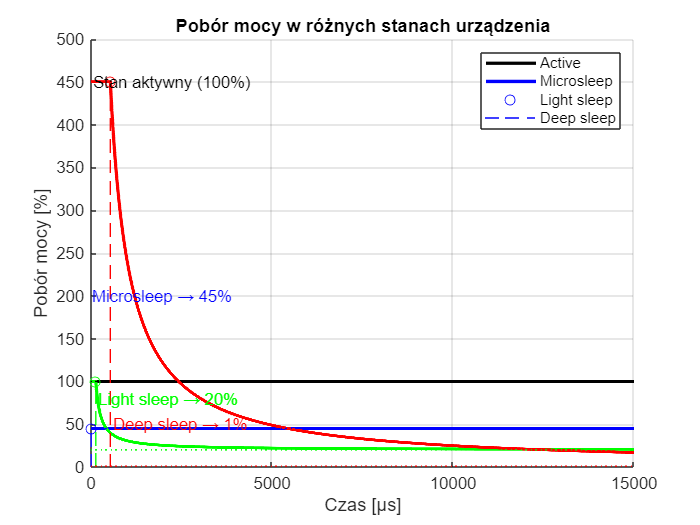

function plot_power_states()
    % Parametry stanów
    states = {
        {'Active',   'k',  100, 100,  0},      % [nazwa, kolor, moc_przed, moc_po, czas_przejścia]
        {'Microsleep', 'b',  45,  45,   4},
        {'Light sleep', 'g',  100,  20, 133},
        {'Deep sleep',  'r',  450,   1, 533}
    };
    
    % Zakres czasu
    t_max = 15000;  % mikro sekundy
    t = linspace(0.1, t_max, 10000);  % unikamy t=0
    
    % Inicjalizacja wykresu
    figure;
    hold on;
    grid on;
    xlabel('Czas [µs]');
    ylabel('Pobór mocy [%]');
    title('Pobór mocy w różnych stanach urządzenia');
    
    % Rysowanie każdego stanu
    legends = {};
    for i = 1:length(states)
        state = states{i};
        [name, color, P_before, P_after, t_trans] = deal(state{:});
        
        % Obliczanie mocy dla danego stanu
        P = zeros(size(t));
        for j = 1:length(t)
            if t(j) <= t_trans
                P(j) = P_before;
            else
                % Średnia moc uwzględniająca czas przejścia
                P(j) = (P_before * t_trans + P_after * (t(j) - t_trans)) / t(j);
            end
        end
        
        % Rysowanie
        plot(t, P, 'Color', color, 'LineWidth', 2);
        legends{end+1} = name;
        
        % Zaznaczenie punktu przejścia
        if t_trans > 0
            plot(t_trans, P_before, 'o', 'Color', color, 'MarkerSize', 6);
            line([t_trans t_trans], [0 P_before], 'Color', color, 'LineStyle', '--');
        end
    end
    
    % Dodanie linii pomocniczych
    for i = 1:length(states)
        state = states{i};
        [~, color, ~, P_after, ~] = deal(state{:});
        line([0 t_max], [P_after P_after], 'Color', color, 'LineStyle', ':');
    end
    
    % Legenda i dostosowanie osi
    legend(legends, 'Location', 'northeast');
    ylim([0 500]);
    xlim([0 t_max]);
    
    % Dodatkowe oznaczenia
    text(50, 450, 'Stan aktywny (100%)', 'Color', 'k');
    text(20, 200, 'Microsleep → 45%', 'Color', 'b');
    text(200, 80, 'Light sleep → 20%', 'Color', 'g');
    text(600, 50, 'Deep sleep → 1%', 'Color', 'r');
end

% Wywołanie funkcji
plot_power_states();

% Funkcja do znajdowania przecięć
function [t_intersect, P_intersect] = find_intersection(t1, P1, t2, P2)
    % Interpolacja krzywych i znalezienie przecięć
    t_combined = unique(sort([t1, t2]));
    P1_interp = interp1(t1, P1, t_combined, 'linear');
    P2_interp = interp1(t2, P2, t_combined, 'linear');
    
    diff = P1_interp - P2_interp;
    crossings = find(diff(1:end-1) .* diff(2:end) <= 0);
    
    % Oblicz dokładne przecięcia
    t_intersect = [];
    P_intersect = [];
    for i = crossings
        t_range = [t_combined(i), t_combined(i+1)];
        P1_range = [P1_interp(i), P1_interp(i+1)];
        P2_range = [P2_interp(i), P2_interp(i+1)];
        
        % Rozwiązanie równania liniowego
        A = [1, -1; 1, -1];
        b = [P1_range(1) - P2_range(1); (P1_range(2) - P1_range(1)) - (P2_range(2) - P2_range(1))];
        sol = linsolve(A, b);
        
        t_int = t_range(1) + sol(1);
        P_int = P1_range(1) + sol(2);
        
        t_intersect = [t_intersect; t_int];
        P_intersect = [P_intersect; P_int];
    end
end


% Dane czasowe
t = linspace(0, 15000, 1000); % 0-15 ms

% Obliczanie mocy dla każdego stanu
P_DS = min(450, (450*533 + 1*(t - 533)) ./ t);
P_LS = min(100, (100*133 + 20*(t - 133)) ./ t);
P_MS = 45 * ones(size(t));

% Rysowanie wykresu
figure;
plot(t, P_DS, 'r', 'LineWidth', 2); hold on;
plot(t, P_LS, 'g', 'LineWidth', 2);
plot(t, P_MS, 'b', 'LineWidth', 2);

% Zaznaczanie przecięć
[t_DS_LS, P_DS_LS] = find_intersection(t, P_DS, t, P_LS)

t_DS_LS = -Inf

P_DS_LS = -Inf

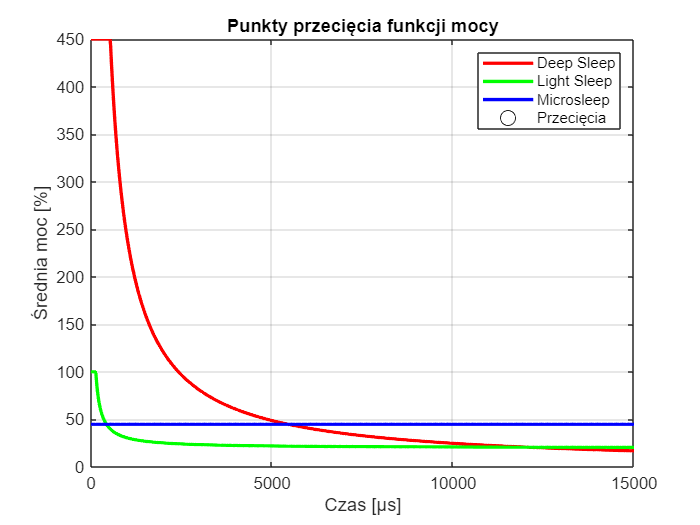

plot(t_DS_LS, P_DS_LS, 'ko', 'MarkerSize', 10);

% Legenda i opis
legend('Deep Sleep', 'Light Sleep', 'Microsleep', 'Przecięcia');
xlabel('Czas [µs]');
ylabel('Średnia moc [%]');
title('Punkty przecięcia funkcji mocy');
grid on;